# Guía 3 - Ejercicio 1

## Enunciado

Hacer una red de Kohonen de 2 entradas que aprenda una distribución uniforme dentro del círculo unitario. Mostrar el mapa de preservación de topología. Probar con distribuciones uniformes dentro de otras figuras geométricas.

Creo los N patrones

clear all
N=500;
patrones = zeros([2 N]);

Patron circular con perimetro

for i=1:N
    aceptado = false;
    while ~aceptado
        aux = rand([2 1]);
        if ((aux(1)-0.5)^2 + (aux(2)-0.5)^2 < 0.5^2)
            patrones(:,i) = (aux-0.5)*2;
            aceptado = true;
        else
            aceptado = false;
        end
    end
end

Creo 4*N patrones en el perímetro para evitar el efecto de pinch

patrones = [patrones zeros([2 N])];
for i=1:N
    aux = rand([1])*2*pi;
    patrones(:,N+i) = [cos(aux) sin(aux)];
end

Patron cuadrado

for i=1:N
    patrones(:,i) = rand([2 1])*2-1;
end

Patron semicirculo

angulo_menor=-2.5;
angulo_mayor = 2.5;
for i=1:N
    aceptado = false;
    while ~aceptado
        aux = rand([2 1])*2-1;
        if norm(aux)< 1 && atan2(aux(1),aux(2))<angulo_mayor && atan2(aux(1),aux(2))>angulo_menor
            patrones(:,i) = aux;
            aceptado=true;
        else
            aceptado = false;
        end
    end
end

Patron anillo

for i=1:N
    aceptado = false;
    while ~aceptado
        aux = rand([2 1])*2-1;
        if norm(aux) < 1 && norm(aux) >0.5
            patrones(:,i) = aux;
            aceptado = true;
        else
            aceptado = false;
        end
    end
end

Patron circular con pequeño circulo

for i=1:N
    aceptado = false;
    while ~aceptado
        aux = rand([2 1]);
        if ((aux(1)-0.5)^2 + (aux(2)-0.5)^2 < 0.5^2)
            patrones(:,i) = (aux-0.5)*2;
            aceptado = true;
        else
            aceptado = false;
        end
    end
end

patrones = [patrones zeros([2 100])];

for i=1:100
    aceptado = false;
    while ~aceptado
        aux = rand([2 1]);
        if ((aux(1)-0.5)^2 + (aux(2)-0.5)^2 < 0.5^2)
            patrones(:,N+i) = (aux-0.5)*0.2+[0.5;0];
            aceptado = true;
        else
            aceptado = false;
        end
    end
end

Muestro la distribución de patrones

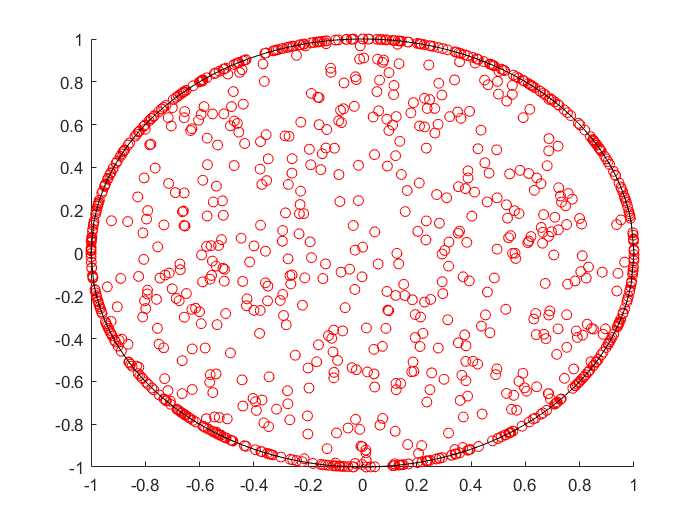

figure()
hold on
x = -1:0.01:1;
scatter(patrones(1,:), patrones(2,:), 'red')
axis([-1 1 -1 1])
plot(x,sqrt(1-x.^2),'k')
plot(x,-1*sqrt(1-x.^2),'k')

Creo la matriz de pesos sinápticos

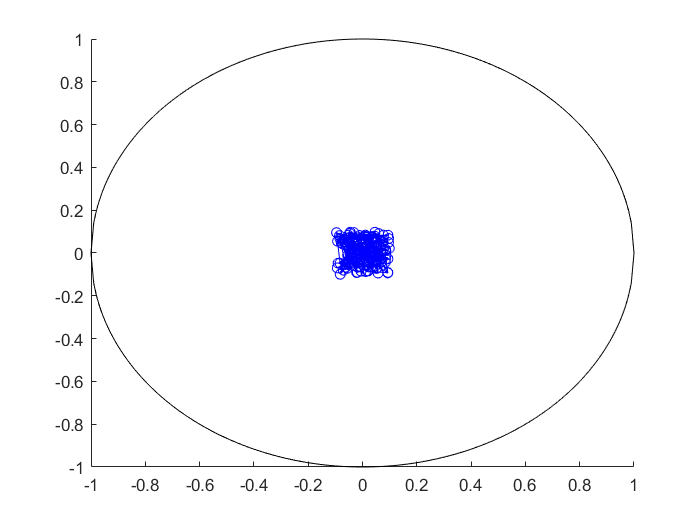

T = 10;
matriz = rand([T T 2]);
matriz = matriz/5-0.1;
%matriz(:,:,1) = matriz(:,:,1)-0.8;

%matriz(1,1,:) = [-0.2 0.2];
%matriz(1,T,:) = [0.2 0.2];
%matriz(T,1,:) = [-0.2 -0.2];
%matriz(T,T,:) = [0.2 -0.2];

figure()
hold on
for j=1:T
    scatter(matriz(:,j,1), matriz(:,j,2),'blue')
    plot(matriz(:,j,1), matriz(:,j,2),'blue')
    plot(matriz(j,:,1), matriz(j,:,2),'blue')
end
axis([-1 1 -1 1])
plot(x,sqrt(1-x.^2),'k')
plot(x,-1*sqrt(1-x.^2),'k')

Entreno grueso

sigma = 3;
eta = 0.01;

for epoch=1:50
    orden = randperm(length(patrones));
    for k = 1:length(patrones)
        mascara = zeros([T T]);
        %elijo un vector
        elegido = patrones(:,orden(k));
        %busco al mayor de las neuronas y obtengo la posición en espacio neurona
        matriz_elegido = ones([T T 2]);
        matriz_elegido(:,:,1) = matriz_elegido(:,:,1)*elegido(1);
        matriz_elegido(:,:,2) = matriz_elegido(:,:,2)*elegido(2);
        diferencia = matriz_elegido-matriz;
        norma = (diferencia(:,:,1).^2+diferencia(:,:,2).^2).^(1/2);
        [valor,posicion] = min(norma(:));
        pos_y = mod(posicion,10);
        if pos_y==0
            pos_y=10;
        end
        pos_x = (posicion-pos_y)/10+1;
        %creo la matriz de pesos de update
        for l = 1:T
            for m = 1:T
                %mascara(l,m) = (1-((l-pos_x)/(sigma*1.5))^2*((m-pos_y)/(sigma*1.5))^2)*exp(-((l-pos_x)^2+(m-pos_y)^2)/(2*sigma^2));
                mascara(m,l) = exp(-((l-pos_x)^2+(m-pos_y)^2)/(2*sigma^2));
            end
        end
        delta = eta*(diferencia).*mascara;
        matriz(:,:,1) = matriz(:,:,1)+ delta(:,:,1);
        matriz(:,:,2) = matriz(:,:,2)+ delta(:,:,2);

    end
    sigma = sigma-0.014;
    %eta = eta*0.995;
end

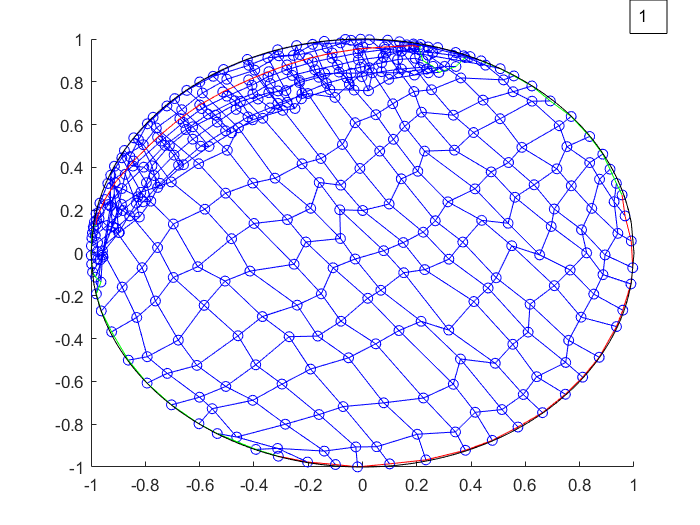

figure()
hold on
for j=1:T
    scatter(matriz(:,j,1), matriz(:,j,2),'blue')
    if j==1 || j==T
        plot(matriz(:,j,1), matriz(:,j,2),'green')
        plot(matriz(j,:,1), matriz(j,:,2),'red')
    else
        plot(matriz(:,j,1), matriz(:,j,2),'blue')
        plot(matriz(j,:,1), matriz(j,:,2),'blue')
    end
    plot(x,sqrt(1-x.^2),'k')
    plot(x,-1*sqrt(1-x.^2),'k')
end
axis([-1 1 -1 1])

Entreno fino

sigma = 2;
eta = 0.05;

for epoch=1:200
    orden = randperm(length(patrones));
    for k = 1:length(patrones)
        mascara = zeros([T T]);
        %elijo un vector
        elegido = patrones(:,orden(k));
        %busco al mayor de las neuronas y obtengo la posición en espacio neurona
        matriz_elegido = ones([T T 2]);
        matriz_elegido(:,:,1) = matriz_elegido(:,:,1)*elegido(1);
        matriz_elegido(:,:,2) = matriz_elegido(:,:,2)*elegido(2);
        diferencia = matriz_elegido-matriz;
        norma = (diferencia(:,:,1).^2+diferencia(:,:,2).^2).^(1/2);
        [valor,posicion] = min(norma(:));
        pos_y = mod(posicion,10);
        if pos_y==0
            pos_y=10;
        end
        pos_x = (posicion-pos_y)/10+1;
        %creo la matriz de pesos de update
        for l = 1:T
            for m = 1:T
                %mascara(l,m) = (1-((l-pos_x)/(T/4))^2*((m-pos_y)/(T/4))^2)*exp(-((l-pos_x)^2+(m-pos_y)^2)/(2*sigma^2));
                mascara(m,l) = exp(-((l-pos_x)^2+(m-pos_y)^2)/(2*sigma^2));

            end
        end
        delta = eta*(diferencia).*mascara;
        matriz(:,:,1) = matriz(:,:,1)+ delta(:,:,1);
        matriz(:,:,2) = matriz(:,:,2)+ delta(:,:,2);

    end
    if sigma>0.1
        sigma = sigma-0.014;
    end
    eta = eta*0.999;
end

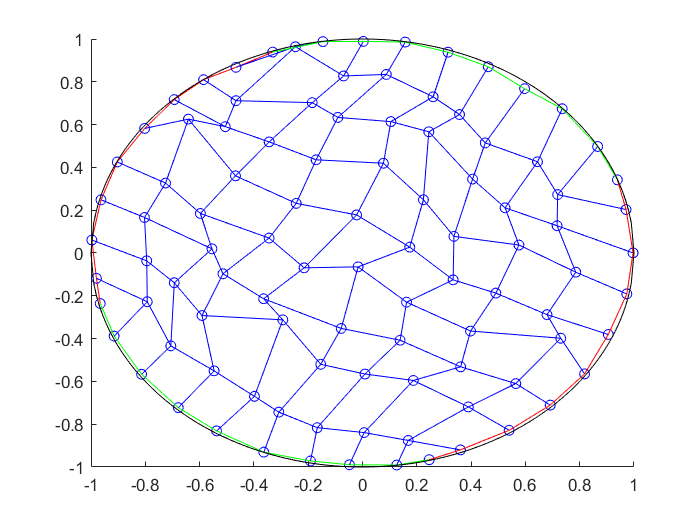

figure()
%scatter(patrones(1,:), patrones(2,:), 'red','MarkerEdgeAlpha',0.5)
hold on
for j=1:T
    scatter(matriz(:,j,1), matriz(:,j,2),'blue')
    if j==1 || j==T
        plot(matriz(:,j,1), matriz(:,j,2),'green')
        plot(matriz(j,:,1), matriz(j,:,2),'red')
    else
        plot(matriz(:,j,1), matriz(:,j,2),'blue')
        plot(matriz(j,:,1), matriz(j,:,2),'blue')
    end
    plot(x,sqrt(1-x.^2),'k')
    plot(x,-1*sqrt(1-x.^2),'k')
end
axis([-1 1 -1 1])